clc;  % Clear command window.
clear;  % Delete all variables.
close all;  % Close all figure windows except those created by imtool.
imtool close all; 
mkdir('Preprocessed');

Training Phase

% structure information
phase_dir = 'TrainSet';
train_set = create_struct(phase_dir);

% preprocessing
preprocessing(train_set);

% feature extraction
[X_LBP_train, X_HOG_train, Y_train] = extract_feature(train_set);

% fitting
X_train = horzcat(X_LBP_train, X_HOG_train);
Mdl = fitcecoc(X_train,Y_train);

Test Phase

% structure information
phase_dir = 'TestSet';
test_set = create_struct(phase_dir);

% preprocessing
preprocessing(test_set);

% feature extraction
[X_LBP_test, X_HOG_test, Y_test] = extract_feature(test_set);

% prediction
X_test = horzcat(X_LBP_test, X_HOG_test);
label = predict(Mdl,X_test);

Stats

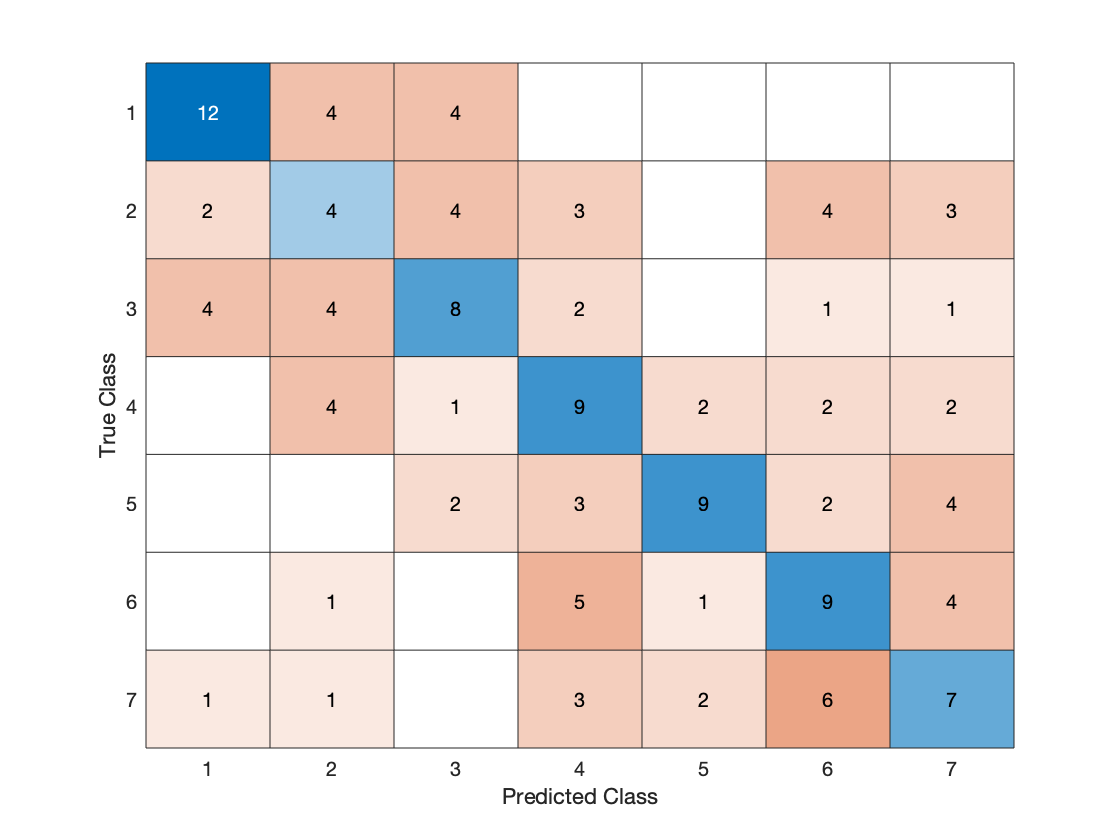

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [7×7 double]
         ClassLabels: [1 2 3 4 5 6 7]

  Show all properties


[correct_classified, misclassified] = compute_misclassified(label, Y_test);

stats = print_results(label, Y_test);


stat_table = struct2table(stats)

stat_table = 7×10 table
      class      TP    TN     FP    FN    accuracy    precision    sensitivity    specificity      F1   
    _________    __    ___    __    __    ________    _________    ___________    ___________    _______

    {'cmptr'}    12    113     7     8    0.89286      0.63158         0.6          0.94167      0.61538
    {'photo'}     4    106    14    16    0.78571      0.22222         0.2          0.88333      0.21053
    {'instr'}     8    109    11    12    0.83571      0.42105         0.4          0.90833      0.41026
    {'rbike'}     9    104    16    11    0.80714         0.36        0.45          0.86667          0.4
    {


correct = 100 * correct_classified

correct = 41.4286

error = 100 * misclassified

error = 58.5714


accuracy = 100 * mean(horzcat(stats.accuracy))

accuracy = 83.2653

precision = 100 * mean(horzcat(stats.precision))

precision = 42.6578

sensitivity = 100 * mean(horzcat(stats.sensitivity))

sensitivity = 41.4286

specificity = 100 * mean(horzcat(stats.specificity))

specificity = 90.2381

F1_score = mean(horzcat(stats.F1))

F1_score = 0.4166

Function used to collect useful information of the dataset, such as the path of the images and the classes

function images_struct = create_struct(phase_dir)

    dataset_dir = 'Dataset';
    phase_path = strcat('./', dataset_dir, '/', phase_dir);
    
    % select only the class directory
    files = dir(phase_path);
    files(ismember( {files.name}, {'.', '..'})) = [];
    flag_dir = [files.isdir];
    class_dirs = files(flag_dir);
    
    % prealloco struct train
    images_struct(length(class_dirs)) = struct();
    
    % for all the classes
    for k = 1 : length(class_dirs)
        class_dirs(k).name; %output della classe
        all_images = strcat(phase_path, '/', class_dirs(k).name, '/', '*.jpg');
        class_dir_images = dir(all_images);
    
        % preallocation 
        images_path = strings(1,length(class_dir_images));
        
        % for all the images in a class
        for j = 1:length(class_dir_images)
            image_name = class_dir_images(j).name;
            class_path = strcat(phase_dir, '/', class_dirs(k).name, '/', image_name);
            images_path(j) = class_path;
        end
   
        images_struct(k).class_dir = class_dirs(k).name;
        images_struct(k).class = encode_class(class_dirs(k).name);
        images_struct(k).images = images_path;
        images_struct(k).set = phase_dir;
    end
    
end

Overall function used to preprocess the data

function preprocessing(data_struct)

    dir_path = strcat('Preprocessed/', data_struct(1).set);
    mkdir(dir_path);
    
    % for all the class
    for k = 1:length(data_struct)
        mkdir(strcat(dir_path, '/', data_struct(k).class_dir));
        % for all the images in a class
        for j = 1:length(data_struct(k).images)
            im_path = data_struct(k).images(j);
            preprocess_image(im_path);
        end
    end
end


Step of the preprocess

function preprocess_image(im_path)
    source_dir = strcat('Dataset/', im_path);
    dest_dir = strcat('Preprocessed/', im_path);
    
    % preprocessing steps
    img = imread(source_dir); 
    img = rgb2gray(img);
    %img = imgaussfilt(img,2); % smooth
    img = imresize(img,[256 256]);
    img = histeq(img);
    imwrite(img, dest_dir);
end

Function used to extract the features (LBP and HOG) 

function [X_LBP, X_HOG, Y] = extract_feature(data_struct)
    
    % preallocation
    features_struct(length(data_struct)*length(data_struct(1).images)) = struct();
    
    % for all the classes
    for k = 1:length(data_struct)
        % for all the images in the class
        for j = 1:length(data_struct(k).images)
            
            im_path = strcat('Preprocessed/', data_struct(k).images(j));
            img = imread(im_path);
            
            %LBP_features = extractLBPFeatures(img);
            %HOG_features = extractHOGFeatures(img);
            LBP_features = extractLBPFeatures(img, 'CellSize',[16 16], "NumNeighbors", 12, "Radius", 3);
            HOG_features = extractHOGFeatures(img, 'CellSize', [12 12]);
            
            index = (k - 1) * length(data_struct(k).images) + j;
            features_struct(index).X_LBP = LBP_features;
            features_struct(index).X_HOG = HOG_features;
            features_struct(index).Y = data_struct(k).class;
        end
    end
    
    % stack the arrays
    X_LBP = vertcat(features_struct.X_LBP);
    X_HOG = vertcat(features_struct.X_HOG);
    Y = char(features_struct.Y);

end

Function used to encode the class name in 5 char

function code = encode_class(name)
    switch name
        case 'Interacting with computer'
            code = 'cmptr';
        case 'Photographing'
            code = 'photo';
        case 'Playing Instrument'
            code = 'instr';
        case 'Riding Bike'
            code = 'rbike';
        case 'Riding Horse'
            code = 'horse';
        case 'Running'
            code = 'runng';
        case 'Walking'
            code = 'wlkng';
        otherwise
            code = 'error';
    end
end



Function used to collect statistics about the prediction

function stats = print_results(label, Y_predicted)
    
    order = {'cmptr', 'photo', 'instr', 'rbike', 'horse', 'runng', 'wlkng'};
    
    [C, order] = confusionmat(Y_predicted,label, 'Order', order);
    confusionchart(C)
    
    % preallocation
    stats(length(order)) = struct();

    for k = 1:length(order)
        
        stats(k).class = order(k, :);
        
        TP = C(k,k);
        FP = sum(C(:,k)) - C(k,k);
        FN = sum(C(k,:)) - C(k,k);
       
        tempC = C;
        tempC(:, k) = [];
        tempC(k, :) = [];
        TN = sum(tempC,'all');
        
        stats(k).TP = TP;
        stats(k).TN = TN;
        stats(k).FP = FP;
        stats(k).FN = FN;
        
        
        stats(k).accuracy = (TP + TN) / (TP + TN + FP + FN);
        stats(k).precision = TP / (TP + FP);
        stats(k).sensitivity = TP / (TP + FN);
        stats(k).specificity = TN / (TN + FP);
        stats(k).F1 = (2 * TP) / ((2 * TP) + FP + FN);
        
    end
end

Function used to compute the number of sample classified correcly / incorrectly

function [correct, error] = compute_misclassified(label, Y_predicted)
    num_correct = 0;
    for k = 1: length(label)
        if ( strcmp( label(k,:), Y_predicted(k,:) ) ) 
            num_correct = num_correct + 1;
        end
    end
    
    correct = num_correct / length(label);
    error = 1 - correct;
end